# Show  Diagram FP demo

Use ShowDiagramFP function to show the Fuel-Product diagram.

### **Read Data Model**

file = "C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data = ReadDataModel(file);

### **Build Diagram FP**

Get the DiagramFP results info and save it into a file

res=DiagramFP(data,'SaveAs','DiagramFP.xlsx');

INFO: cMessageLogger. Diagram FP is saved in file DiagramFP.xlsx


### Plot Diagram FP

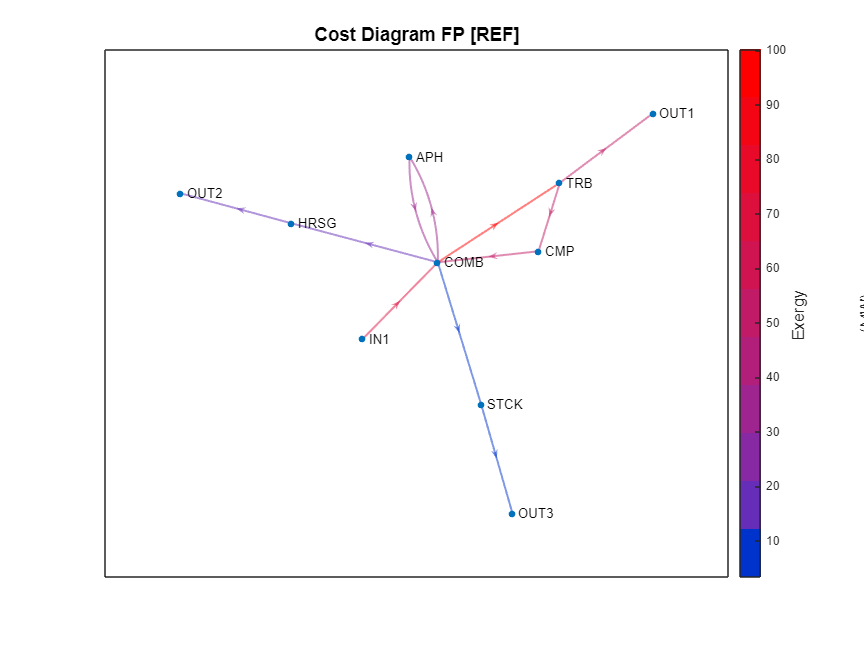

ShowGraph(res,'Graph',cType.Tables.COST_DIAGRAM_FP);

### Additional Help Information

help DiagramFP

 DiagramFP - Gets the diagram FP tables for one plant State
    This function gets the adjacency tables of the diagram FP
    for one state of the plant. 
    These diagrams could be represented grafically using the function
    ShowGraph, or by external graph software as yEd saving the adjancency
    tables of the graph in xlsx format.
   	
    Syntax
      res = DiagramFP(data,Name,Value);
 
    Input Arguments
      data - cReadModel Object containing the data model information.
 
    Name-Value Arguments
      State - Indicate one valid state to get exergy values. 
        char array
      Show -  Show results on console
        true | false (default)
      SaveAs - Name of the file where the results are saved.
        char array | string
 
    Output Arguments
      res - cResultInfo object contains the FP diagram tables
       The following tables are obtained:
        atfp - Diagram FP adjacency matrix                                     
      